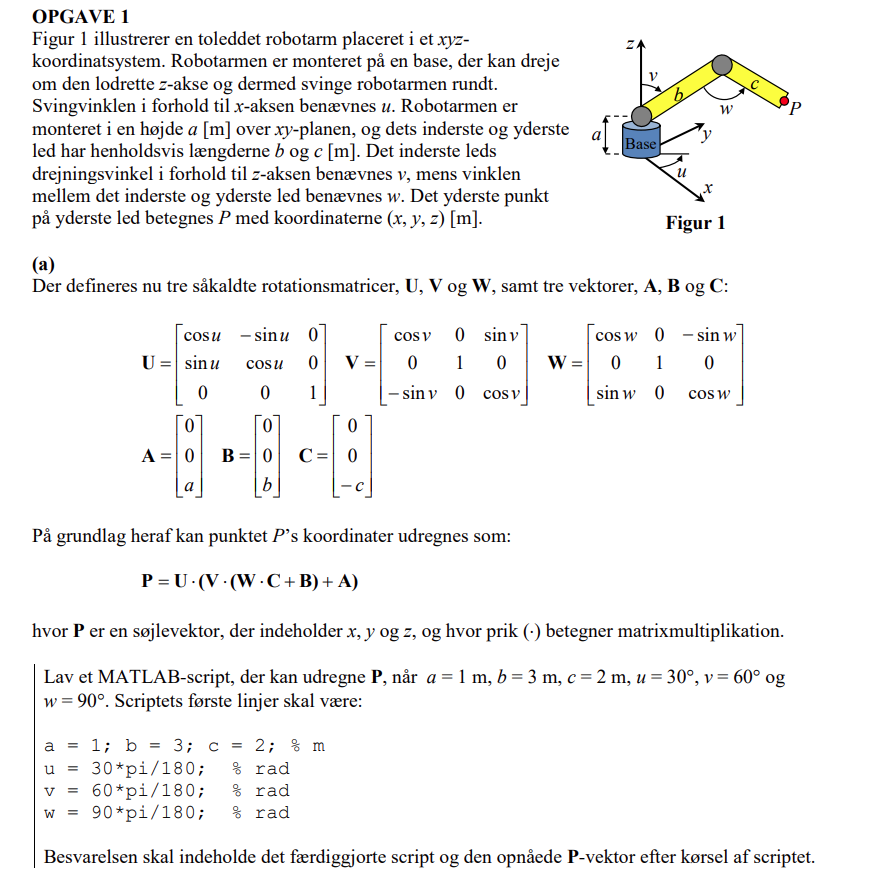

a = 1; b = 3; c = 2; % m
u = 30*pi/180; % rad
v = 60*pi/180; % rad
w = 90*pi/180; % rad

%Matricerne opskrives
U = [cos(u) -sin(u) 0
    sin(u) cos(u) 0
    0 0 1];
V = [cos(v) 0 sin(v)
    0 1 0
    -sin(v) 0 cos(v)];
W = [cos(w) 0 -sin(w)
    0 1 0
    sin(w) 0 cos(w)];

%Vektorende opskrives
A = [0; 0; a];
B = [0; 0; b];
C = [0; 0; -c];

%Der udregnes hvor resultatet bliver en vektor
P = U * (V * (W * C + B) + A) %Rækkefølgen af matricerne er ikke ligegyldig 

P =         3.116
        1.799
      0.76795


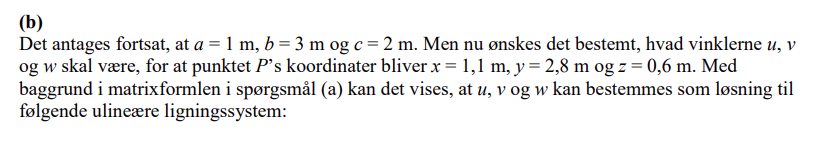

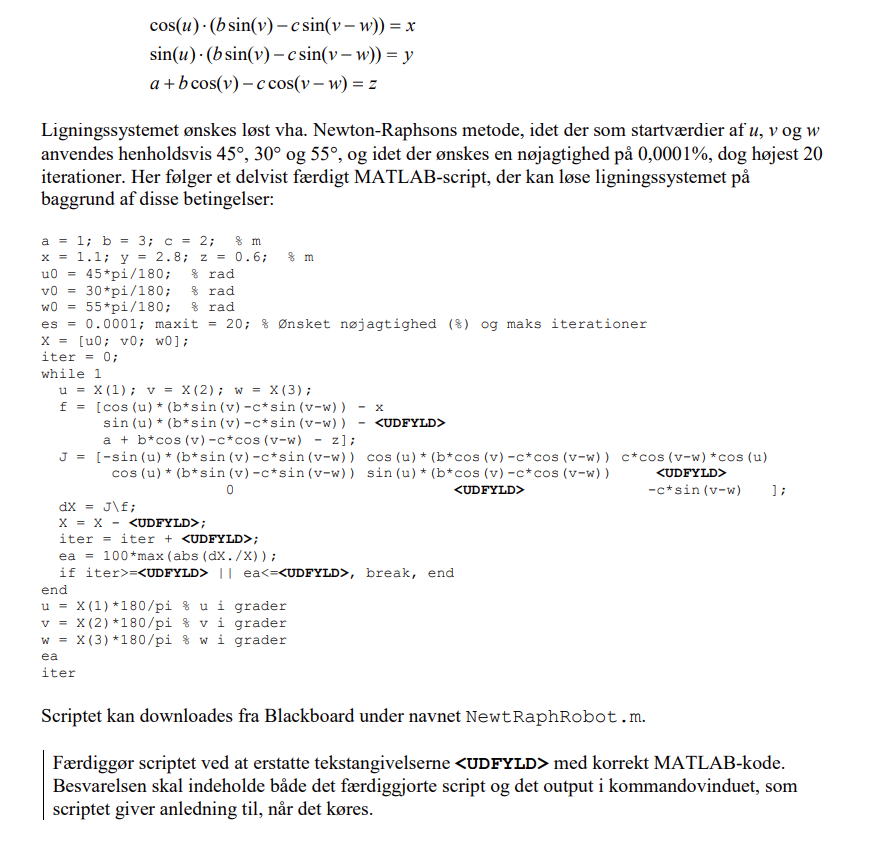

clear
syms u v w x y z a b c
f = [cos(u)*(b*sin(v)-c*sin(v-w)) - x
        sin(u)*(b*sin(v)-c*sin(v-w)) - y
        a + b*cos(v)-c*cos(v-w) - z];
jacobian(f, [u,v,w])

$$ans = \begin{array}{l} \left(\begin{array}{ccc} -\sin\left(u\right)\,\sigma_{2} & \cos\left(u\right)\,\sigma_{1} & c\,\cos\left(v-w\right)\,\cos\left(u\right)\\ \cos\left(u\right)\,\sigma_{2} & \sin\left(u\right)\,\sigma_{1} & c\,\cos\left(v-w\right)\,\sin\left(u\right)\\ 0 & \sigma_{3}-b\,\sin\left(v\right) & -\sigma_{3} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=b\,\cos\left(v\right)-c\,\cos\left(v-w\right)\\ \sigma_{2}=b\,\sin\left(v\right)-\sigma_{3}\\ \sigma_{3}=c\,\sin\left(v-w\right) \end{array}$$



a = 1; b = 3; c = 2; % m
x = 1.1; y = 2.8; z = 0.6; % m
u0 = 45*pi/180; % rad
v0 = 30*pi/180; % rad
w0 = 55*pi/180; % rad
es = 0.0001; maxit = 20; % Ønsket nøjagtighed (%) og maks iterationer
X = [u0; v0; w0];
iter = 0;
while 1
    u = X(1); v = X(2); w = X(3);

    f = [cos(u)*(b*sin(v)-c*sin(v-w)) - x

        sin(u)*(b*sin(v)-c*sin(v-w)) - y

        a + b*cos(v)-c*cos(v-w) - z];

    J = [-sin(u)*(b*sin(v)-c*sin(v-w)) cos(u)*(b*cos(v)-c*cos(v-w)) c*cos(v-w)*cos(u)
        cos(u)*(b*sin(v)-c*sin(v-w)) sin(u)*(b*cos(v)-c*cos(v-w)) c*cos(v-w)*sin(u)
        0 c*sin(v-w)-b*sin(v) -c*sin(v-w)];

    dX = J\f;

    X = X - dX;

    iter = iter + 1;

    ea = 100*max(abs(dX./X));

    
    if iter>=20 || ea<=es
        break
    end
end
u = X(1)*180/pi % u i grader

u =        68.552


v = X(2)*180/pi % v i grader

v =         58.87


w = X(3)*180/pi % w i grader

w =        71.589


ea

ea =    4.5887e-05


iter

iter =      5


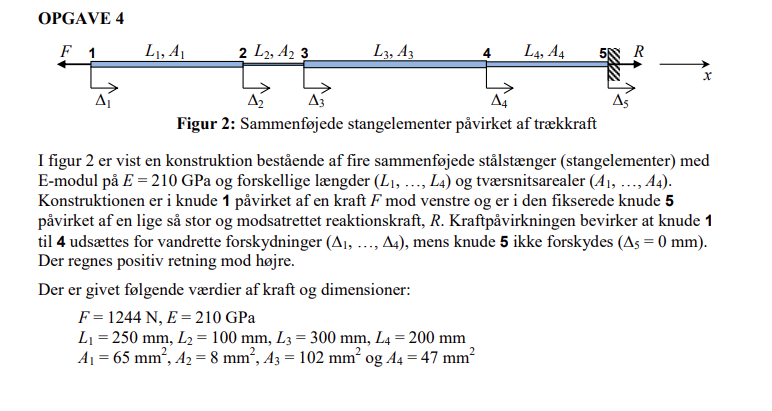

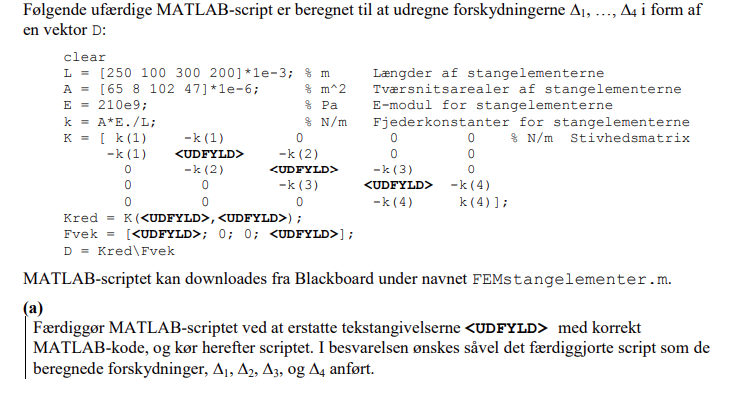

clear
L = [250 100 300 200]*1e-3; % m Længder af stangelementerne
A = [65 8 102 47]*1e-6; % m^2 Tværsnitsarealer af stangelementerne
E = 210e9; % Pa E-modul for stangelementerne
k = A*E./L; % N/m Fjederkonstanter for stangelementerne
K = [ k(1) -k(1) 0 0 0 % N/m Stivhedsmatrix
    -k(1) k(1)+k(2) -k(2) 0 0
    0 -k(2) k(2)+k(3) -k(3) 0
    0 0 -k(3) k(3)+k(4) -k(4)
    0 0 0 -k(4) k(4)];

Kred = K(1:4,1:4);
F = 1244; %N
Fvek = [F; 0; 0; F];
D = Kred\Fvek;

format("shortG")
tab = table(D, VariableNames={'Forskydning i punkt'})

tab = 4×1 table
    Forskydning i punkt
    ___________________

        0.00016467     
        0.00014189     
        6.7838e-05     
        5.0415e-05     


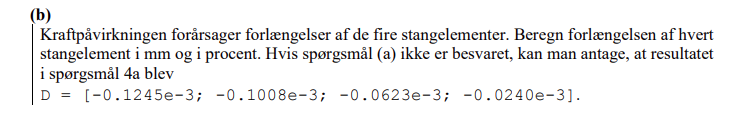

%flipper vectorne
D_lang = flip(D);
L_rev = flip(L);

%start værdiger til forloop
d = 0;
forlaengelse = [];
d_proc = [];

%forloop udregner forlængelserne
for i = 1:length(L) 
     d = D_lang(i) - d;
     forlaengelse(i) = d * 1000;
     d_proc(i) = d/L_rev(i) * 100;
end

%tabel for klarhed
clear table
tab_delta = table(flip(forlaengelse'), flip(d_proc'), VariableNames={'Forlængelse i mm', 'Forlængelse i %'})

tab_delta = 4×2 table
    Forlængelse i mm    Forlængelse i %
    ________________    _______________

        0.040207            0.016083   
         0.12446             0.12446   
        0.017423           0.0058077   
        0.050415            0.025208   


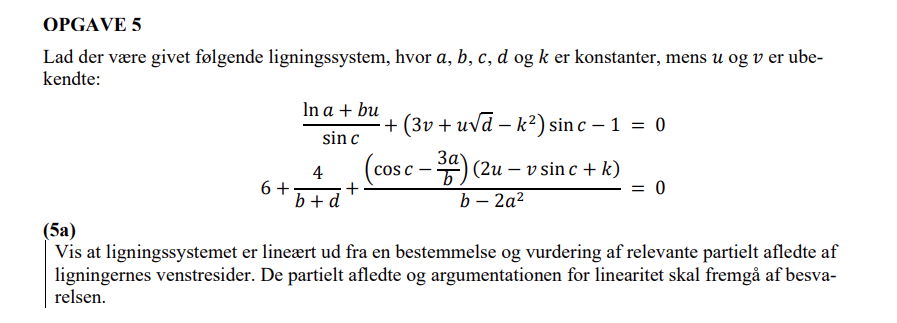

%% Konstanter sættes til 1 og u og v sættes til symboler, der evalueres for at få en ligning som gerne skulle være linær. 
syms u v
a = 1;
b = 1;
c = 1;
d = 1;
k = 1;
func1 = (log(a)+b*u)/sin(c)+(3*v + u * sqrt(d)-k^2)*sin(c)-1

$$func1 = \frac{34643844702534016924092238187345\,u}{17067059183461908934129239457792}+\frac{11368945240871781\,v}{4503599627370496}-\frac{8293248040994423}{4503599627370496}$$

%%Vi kan se at formen af funktione er linær, for at evaluere det så differentieres den, vis den er linær burde vi gerne kun have 1 hældning. 

vpa(diff(func1, u), 4)

$$ans = 2.03$$

vpa(diff(func1, v), 4)

$$ans = 2.524$$

%% vi har kun 1 hældning derfor må funktion 1 være linær, dette gøres igen for function 2. 

func2=6+4/(b+d)+(cos(c)-3*a/b)*(2*u-v*sin(c)+k)/(b-2*a^2) 

$$func2 = \frac{5538746809368157\,u}{1125899906842624}-\frac{20989903059586623388313487092539\,v}{10141204801825835211973625643008}+\frac{23553145318850141}{2251799813685248}$$

vpa(diff(func2, u), 4)

$$ans = 4.919$$

vpa(diff(func2, v), 4)

$$ans = -2.07$$

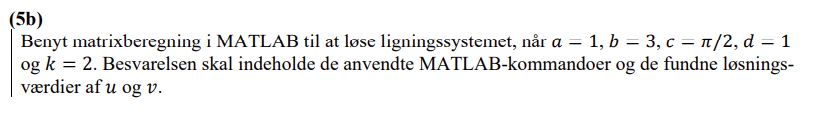

a = 1;
b = 3;
c = pi/2;
d = 1;
k = 2;


eqs = [func1 == 0; func2 == 0]; %definer en simpel 2x1 matrice
[A,B] = equationsToMatrix(eqs) %Bruger indbygget function til at omdanne 2x1 matrice til et matrice lignigns system. 

$$A = \left(\begin{array}{cc} \frac{34643844702534016924092238187345}{17067059183461908934129239457792} & \frac{11368945240871781}{4503599627370496}\\ \frac{5538746809368157}{1125899906842624} & -\frac{20989903059586623388313487092539}{10141204801825835211973625643008} \end{array}\right)$$

$$B = \left(\begin{array}{c} \frac{8293248040994423}{4503599627370496}\\ -\frac{23553145318850141}{2251799813685248} \end{array}\right)$$

X = vpa(linsolve(A,B),5) %solver for matricen

$$X = \left(\begin{array}{c} -1.3594\\ 1.8226 \end{array}\right)$$